# Interferogram Network Selection

Zel Hurewitz, July 2024

## Before You Start

#### Interferogram List Generation

Generate a list of all the URLs of the query interferograms and place them in a list in a text file. The file should look like below. The downloadAvailableURLs_ARIA.m functi on will do this automatically.

Note: This program is blind to the *spatial* extent of interferograms. The downloadAvailableURLs_ARIA.m function automatically downloads the URLs of all frame files which intersect the given bounding box. If using another tool, it is the user's resposibility to ensure that spatial converage of multiple interferogram frames is complete for each interferogram. 

Note: The URL path (https://grfn.asf.alaska.edu/door/download/) is not important to the successful completion of this program. However, only ARIA and HyP3 interferogram formats are currently available. Contact the author if you wish to add support for another file format.

## Input and Output

Select the file with the list of URLs. If the file path is already correct, you do not need to do anything.

listfilename= "/Users/zhurewit/Workspace/MATLAB/WORK/BInSAR Development/Data/NetworkSelection/allAvailableURLs_S1_144_ARIA_v3_0_1.txt";

filelist= readlines(listfilename);

metaData= io.shortMetaData(filelist);


The output folder is automatically populated with the selected network list and the window information. The information is saved in simple text files. 

outputDirectory= "/Users/zhurewit/Workspace/MATLAB/WORK/BInSAR Development/Data/NetworkSelection";

#### Mission and Track Selection

An interferogram network is specfic for each satellite mission and track. For consistency, the processing center and version number must also be specified.

ProcessingCenters= unique(metaData.ProcessingCenter);
ProcessingCenter= ProcessingCenters(1);
I= strcmpi(metaData.ProcessingCenter,ProcessingCenter);
metaData= metaData(I,:);

Missions= unique(metaData.Mission);
Mission= Missions(1);
I= strcmpi(metaData.Mission,Mission);
metaData= metaData(I,:);

Tracks= string(unique(metaData.Track));
Track= str2double(Tracks(1));
I= metaData.Track == Track;
metaData= metaData(I,:);

Versions= unique(metaData.Version);
Version= Versions(1);
I= strcmpi(metaData.Version,Version);
metaData= metaData(I,:);


## Network Selection

#### Background Temporal Baseline

The background temporal baseline is the default maximum allowed length of time interferograms are allowed to be created over.

backgroundBaseline= 48;


### Custom Windows

Windows are an optional tool to customize the interferogram network by allowing longer interferograms over limited timespans. The window must be active and the start and end dates must be specified for it to be applied to the network.

#### Window 1

window1active= true;
window1start= datetime("2014-11-01", "InputFormat", "uuuu-MM-dd");
window1end= datetime("2015-06-01", "InputFormat", "uuuu-MM-dd");
window1baseline= 192;

#### Window 2

window2active= true;
window2start= datetime("2015-06-01", "InputFormat", "uuuu-MM-dd");
window2end= datetime("2016-10-01", "InputFormat", "uuuu-MM-dd");
window2baseline= 120;

#### Window 3

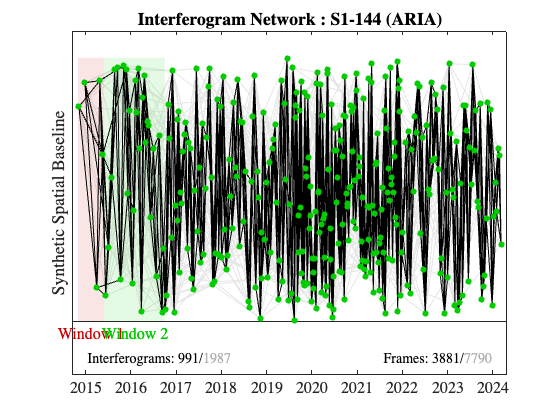

window3active= false;
window3start= datetime("2021-11-01", "InputFormat", "uuuu-MM-dd");
window3end= datetime("2022-04-30", "InputFormat", "uuuu-MM-dd");
window3baseline= 120;

I= networkLogic(metaData,backgroundBaseline,...
    window1active,window1start,window1end,window1baseline,...
    window2active,window2start,window2end,window2baseline,...
    window3active,window3start,window3end,window3baseline);

% Plot
plotInterferogramNetwork(metaData,I,Mission,Track,ProcessingCenter,...
    window1active,window1start,window1end,window1baseline,...
    window2active,window2start,window2end,window2baseline,...
    window3active,window3start,window3end,window3baseline);


% Save image
name= sprintf('network-%s-%d-%s-%s%',Mission,Track,ProcessingCenter,Version);
saveAsPNG= false;
if saveAsPNG
    imagename= fullfile(outputDirectory,strcat(name,'.png'));
    imwrite(getframe(gcf).cdata,imagename)
end
saveAsPDF= false;
if saveAsPDF
    imagename= fullfile(outputDirectory,strcat(name,'.pdf'));
    exportgraphics(gcf,imagename,'ContentType','vector')
end

#### Detailed Figure Legend

- Green point: A connected network whose edges make cycles

- Red point: A network unconnected to the green network

- Purple point: An isolated node

- Orange triangle: A node which is not part of a cycle

- Colorful boxes: The active windows

- Black lines: The current interferogram network

- Grey lines: The superset of all interferograms

Tip: Pop the figure out to manipulate the figure and adjust the size. Save as a PDF using the exportgraphics function.

Technical note: The window applies the custom baseline to all interferograms whose *reference* (i.e. first) SAR posting intersects with the window.

## Save Interferogram Network

Write the list of URLs to a text file, a Python bulk download script, and save the window information.

 
downloadList= metaData.Fullname(I);

% Save data
name= sprintf('selectedURLs-%s-%d-%s-%s%',Mission,Track,ProcessingCenter,Version);
savefile= fullfile(outputDirectory,strcat(name,'.txt'));
writelines(downloadList,savefile)

% Save information
T= table;
T.Start= [NaT; window1start; window2start; window3start];
T.End= [NaT; window1end; window2end; window3end];
T.Active= [true; window1active; window2active; window3active];
T.Baseline= [backgroundBaseline; window1baseline; window2baseline; window3baseline];
name= sprintf('windowInfo-%s-%d-%s-%s%',Mission,Track,ProcessingCenter,Version);
infofile= fullfile(outputDirectory,strcat(name,'.txt'));
writetable(T,infofile)

% Save bulk download script
Text= readlines("basedownloadScript.py");
Text= replace(Text,"\","\\"); % Replace literal characters
Text= replace(Text,"%","%%");
k= find(contains(Text,'###FILENAMES###'));
Line= replace(Text(k), '###FILENAMES###', strjoin(strcat('"', downloadList, '"'),",\n"));
Text(k)= Line;
tag= sprintf('%s-%d-%s-%s%',Mission,Track,ProcessingCenter,Version);
downloadname= fullfile(outputDirectory,strcat('downloadScript-',tag,'.py'));
fid= fopen(downloadname,'w');
warning off
fprintf(fid,strjoin(Text,'\n'));
warning on
fclose(fid);

### More about Interferograms and Good Network Selection

Interferograms can be generated from any pair of Single Look Complices (SLCs). This can be done either through an On-Demand system such as the HyP3 processing on [ASF Vertex](https://search.asf.alaska.edu/#/), or by downloading pre-generated interferograms, such as JPL's ARIA products, which are also available through ASF. 

Sets of interferograms form the edges of an **interferogram network**, which can be visualized as a graph where the nodes correspond to each timestep (a **SAR posting**) used to construct any interferogram. Taken as a network, interferograms can be used to estimate timeseries of ground surface motion. 

#### Motivation

Interferograms vary in quality and availability. When created over too long a timespan (known as **temporal baseline**), particularly in dynamic or vegetated regions, the unwrapping algorithm used to estimate physical displacement from the complex radar phase can fail and give erroneous results. Consequently, it is crucial in such regions to reject interferograms more than a month or two long. (Note that the *minimum* temporal baseline is 6 days for the Sentinel-1 mission, and 12 days for NISAR and other missions, corresponding to the satellite orbit revisit time.)

Data availability is not necessarily uniform either, but depends on the number of satellites in orbit, the downlink rate, and other factors. Some time windows need to have a different maximum temporal baseline to ensure that the network is entirely connected, with no missing points or isolated sub-networks. Additionally, it is good practice to have every time covered by multiple interferograms for redundancy, meaning that every interferogram will be part of a [network cycle](https://en.wikipedia.org/wiki/Cycle_(graph_theory)).

%% FUNCTIONS

%% Lines of a graph
function [lx,ly] = graphLines(Graph, t, y)
E= Graph.Edges.EndNodes;

lx= reshape([t(E'); NaT(1,height(E))],1,[]);
ly= reshape([y(E'); nan(1,height(E))],1,[]);
end



%% Date Pairs to Graph
% Generates interferogram graph/network from a set of primary/secondary
% dates
function [Date,G,A]= datePairsToGraph(PrimaryDate,SecondaryDate)

Date= unique([PrimaryDate; SecondaryDate]);

Ndate= length(Date);


I1= sum((PrimaryDate == Date').*(1:Ndate),2);
I2= sum((SecondaryDate == Date').*(1:Ndate),2);

A= false(Ndate);

for i= 1:height(I1)
    A(I1(i),I2(i))= true;
end

A= A | A';

G= graph(A);

end


function I= networkLogic(metaData,backgroundBaseline,...
    window1active,window1start,window1end,window1baseline,...
    window2active,window2start,window2end,window2baseline,...
    window3active,window3start,window3end,window3baseline)

I= metaData.TemporalBaseline <= backgroundBaseline;
if window1active
    I= I | (metaData.PrimaryDate >= window1start & metaData.PrimaryDate <= window1end &...
        metaData.TemporalBaseline <= window1baseline);
end
if window2active
    I= I | (metaData.PrimaryDate >= window2start & metaData.PrimaryDate <= window2end &...
        metaData.TemporalBaseline <= window2baseline);
end
if window3active
    I= I | (metaData.PrimaryDate >= window3start & metaData.PrimaryDate <= window3end &...
        metaData.TemporalBaseline <= window3baseline);
end

end

%% Plot Function
function plotInterferogramNetwork(metaData,I,Mission,Track,ProcessingCenter,...
    window1active,window1start,window1end,window1baseline,...
    window2active,window2start,window2end,window2baseline,...
    window3active,window3start,window3end,window3baseline)

[PostingDate,Gbackground]= datePairsToGraph(metaData.PrimaryDate,metaData.SecondaryDate);

x= PostingDate';
rng(0)
y= rand(1,length(PostingDate));


[x1,G]= datePairsToGraph(metaData.PrimaryDate(I),metaData.SecondaryDate(I));
[~,ia]= intersect(x,x1);
Ia= false(1,length(PostingDate));
Ia(ia)= true;
Iisolated= ~Ia;

C= conncomp(G);
Iunconnected= false(1,length(PostingDate));
Iunconnected(ia)= C ~= mode(C);

Cycles= allcycles(G,"MaxCycleLength",4);
ib= unique(cell2mat(Cycles'));
Ib= false(1,length(PostingDate));
Ib(ib)= true;
Icycleless= ~Ib;

Iconnected= ~Iisolated & ~Iunconnected & ~Icycleless;


[lx,ly]= graphLines(Gbackground,x,y);
plot(lx,ly, 'Color',[0 0 0]+.9);
xlim(PostingDate([1 end])+ [-48; 48])
hold on
% plot(xlim,[1 1],'k')

if window1active
    area([window1start window1start window1end window1end],[0 1 1 0],'FaceColor',[.8 0 0],'FaceAlpha',.1,...
        'EdgeColor','none')
    text(mean([window1start window1end]),...
        -.05,'Window 1','Color',[.8 0 0],'HorizontalAlignment','center',...
        'FontSize',16,'FontName','Times')
end
if window2active
    area([window2start window2start window2end window2end],[0 1 1 0],'FaceColor',[0 .8 0],'FaceAlpha',.1,...
        'EdgeColor','none')
    text(mean([window2start window2end]),...
        -.05,'Window 2','Color',[0 .8 0],'HorizontalAlignment','center',...
        'FontSize',16,'FontName','Times')
end
if window3active
    area([window3start window3start window3end window3end],[0 1 1 0],'FaceColor',[0 0 .8],'FaceAlpha',.1,...
        'EdgeColor','none')
    text(mean([window3start window3end]),...
        -.05,'Window 3','Color',[0 0 .8],'HorizontalAlignment','center',...
        'FontSize',16,'FontName','Times')
end

[lx1,ly1]= graphLines(G,x1,y(Ia));
plot(lx1,ly1, 'Color',[0 0 0]);

scatter(x(Iconnected),y(Iconnected),40,[0 .8 0],'filled')
scatter(x(Iunconnected),y(Iunconnected),40,'r','filled')
scatter(x(~Ib),y(~Ib),100,[1 .8 0],'^','filled')
scatter(x(Ib & ~Ia),y(Ib & ~Ia),60,[.5 0 1],'filled')
hold off

XLIM= xlim;
text(XLIM(1)+ .3*diff(XLIM),-.14,sprintf('Interferograms: %d/',height(G.Edges)),'FontSize',14,'FontName','Times','HorizontalAlignment','right')
text(XLIM(1)+ .3*diff(XLIM),-.14,string(height(Gbackground.Edges)),'FontSize',14,'FontName','Times','Color',[.7 .7 .7])

text(XLIM(1)+ .9*diff(XLIM),-.14,sprintf('Frames: %d/',sum(I)),'FontSize',14,'FontName','Times','HorizontalAlignment','right')
text(XLIM(1)+ .9*diff(XLIM),-.14,string(height(metaData)),'FontSize',14,'FontName','Times','Color',[.7 .7 .7])

set(gca,'FontSize',16,'FontName','Times')
set(gca,'XAxisLocation','bottom')
xlim(PostingDate([1 end])+ [-48; 48])
ylim([-.2 1.1])
yticks([])
ylabel('Synthetic Spatial Baseline')
title(sprintf('Interferogram Network : %s-%d (%s)',Mission,Track,ProcessingCenter))
end